clc
close all
clear all
%% Global variable delaration and common variables
global F H R

Runs = 500;
T = 0.1;             % sampling Time
total_time = 7;
t =0: T: total_time;        % Time vector
TotalScans = length(t);

mean = 0;            % measurement noise mean
meas_noise_sd = 1.2; % measurement noise standard deviation

nstates = 6;         % numbers of States
nmeas = 3;           % number of measurements
init_pos = [15; 15 ; 200]; % True inital Position (m) of the target on x and y axis [x; y]
V = [7; 7; 7];          % True Velocity (m/s) of the target on x and y axis [vx; vy]

%% Kalman Filter

F=[eye(3) T*eye(3);zeros(3) eye(3)]; % Transition matrix for constant velocity model

H=[eye(nmeas) zeros(nstates-nmeas)];   %Output Coeffecient Matrix

R=(meas_noise_sd^2)*eye(nmeas); % measurement covariance matrix

for run = 1 : Runs

    targetX = init_pos(1);
    targetY = init_pos(2);
    targetZ = init_pos(3);
    target_velocityX = V(1);
    target_velocityY = V(2);
    target_velocityZ = V(3);

    for scan = 2 : TotalScans

        targetX(scan) = targetX(scan - 1) + T*target_velocityX;    % True/actual position: all scans
        targetY(scan) = targetY(scan - 1) + T*target_velocityY;    % True/actual position: all scans
        targetZ(scan) = targetZ(scan - 1) + T*target_velocityZ;
    end
    Ztrue = [targetX ; targetY; targetZ ];    % True/Actual target position

    meas_noise = mean + R*randn(nmeas, TotalScans);    % generating measurement noise (gaussian noise)
    Znoisy = Ztrue + meas_noise;                       % The noisy measurment vector
    X0 = [Znoisy(:,1) ; V+diag(R).*randn( size(V) )];                   % inital State for first scan only
    P0 = [R*eye(nmeas)  zeros(nmeas) ; zeros(nmeas)  (R^2)*eye(nmeas)/T];  % inital State Covariacne for first scan only

    Xest = X0;      % inital State declaration (first scan only)
    Pest = P0;
    EstimatedX(run,1) = Xest(1);
    EstimatedY(run,1) = Xest(2);
    EstimatedZ(run,1) = Xest(3);

    Estimated_Vx(run,1) = Xest(4);
    Estimated_Vy(run,1) = Xest(5);
    Estimated_Vz(run,1) = Xest(6);
    for scan = 2 : TotalScans
        Xpred=F*Xest;       % Predicted state vector
        xxx(:,scan)=Xpred;
        Ppred=F*Pest*F';   % Predicted state covariance matrix
        S = H*Ppred*H' + R;     % Innovation covariance
        K = Ppred*H'*inv(S);    % optimal kalman gain
        abc(:,scan)= K*( Znoisy(:,scan) - H*Xpred);
        Xest = Xpred + K*( Znoisy(:,scan) - H*Xpred );    % a-posterori state estimate
        Pest = ( eye(nstates) - K*H )*Ppred;        % a-posterori estimate Covariance




        EstimatedX(run,scan) = Xest(1);
        EstimatedY(run,scan) = Xest(2);
        EstimatedZ(run,scan) = Xest(3);

        Estimated_Vx(run,scan) = Xest(4);
        Estimated_Vy(run,scan) = Xest(5);
        Estimated_Vz(run,scan) = Xest(6);
    end

    Zx(run,:)=Znoisy(1,:);
    Zy(run,:)=Znoisy(2,:);
    Zz(run,:)=Znoisy(3,:);
end

% Averaging the results to eleminate uncertainity (MonteCarlo Runs)

Monte_estimateX = sum(EstimatedX)/Runs;
Monte_estimateX(end)

ans = 63.9719

Monte_estimateY = sum(EstimatedY)/Runs;
Monte_estimateY(end)

ans = 64.0007

Monte_estimateZ = sum(EstimatedZ)/Runs;
Monte_estimateZ(end)

ans = 249.0151

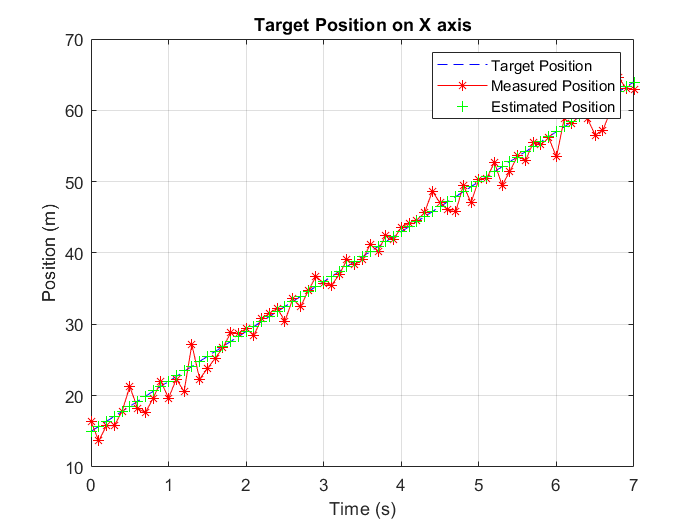

Monte_estimateVx = sum(Estimated_Vx)/Runs;
Monte_estimateVy = sum(Estimated_Vy)/Runs;
Monte_estimateVz = sum(Estimated_Vz)/Runs;
Monte_Znoisyx = sum(Zx)/Runs;
Monte_Znoisyy = sum(Zy)/Runs;
Monte_Znoisyz = sum(Zz)/Runs;
%% Statistics (Root mean Sauare Error)

TruevelocityX = repmat(V(1),Runs, TotalScans);  % generating veloxity vector for x-axis
TruevelocityY = repmat(V(2),Runs, TotalScans);  % generating veloxity vector for y-axis
TruevelocityZ = repmat(V(3),Runs, TotalScans);  % generating veloxity vector for y-axis
RMSEX = sqrt( sum( (repmat(Ztrue(1,:),Runs,1) - EstimatedX).^2 )/Runs ); % Computing Root Mean Square error in x-position
RMSEY = sqrt( sum( (repmat(Ztrue(2,:),Runs,1) - EstimatedY).^2 )/Runs ); % Computing Root Mean Square error in y-position
RMSEZ = sqrt( sum( (repmat(Ztrue(3,:),Runs,1) - EstimatedZ).^2 )/Runs ); % Computing Root Mean Square error in y-position
RMSEVx = sqrt( sum( (TruevelocityX - Estimated_Vx).^2 )/Runs ); % Computing Root Mean Square error in x-velocity
RMSEVy = sqrt( sum( (TruevelocityY - Estimated_Vy).^2 )/Runs ); % Computing Root Mean Square error in y-position
RMSEVz = sqrt( sum( (TruevelocityZ - Estimated_Vz).^2 )/Runs ); % Computing Root Mean Square error in y-position
PositionRMSE = sqrt( RMSEX.^2 + RMSEY.^2+ RMSEZ.^2); % computing the total or resultant position RMSE (both in x and y position)
VelocityRMSE = sqrt( RMSEVx.^2 + RMSEVy.^2 + RMSEVz.^2); % computing the total or resultant velocity RMSE (Both in Vx and Vy)

RMSE = [ PositionRMSE; VelocityRMSE];


%% Plotting
Estimate=[Monte_estimateX; Monte_estimateY;Monte_estimateZ; Monte_estimateVx; Monte_estimateVy ; Monte_estimateVz];
Monte_Znoisy=[Monte_Znoisyx;Monte_Znoisyy;Monte_Znoisyz];
figure
% subplot(311)
% plot(t,Ztrue(1,:),'r','LineWidth',1.5)
% hold on
% plot(t,Znoisy(1,:),'g','LineWidth',1.5)
% hold on
% plot(t,Estimate(1,:),'b','LineWidth',1.5)
plot(t,Ztrue(1,:),'--b',t,Znoisy(1,:),'r-*',t,Estimate(1,:),'g+')
legend('Target Position','Measured Position','Estimated Position')
xlabel('Time (s)')
ylabel('Position (m)')
title('Target Position on X axis')
grid on
hold off

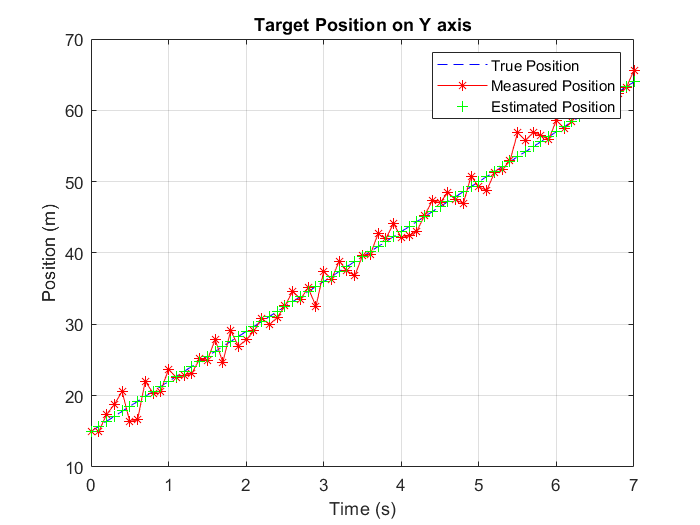

figure
% subplot(312)
% plot(t,Ztrue(2,:),'r','LineWidth',1.5)
% hold on
% plot(t,Znoisy(2,:),'g','LineWidth',1.5)
% hold on
% plot(t,Estimate(2,:),'b','LineWidth',1.5)
plot(t,Ztrue(2,:),'--b',t,Znoisy(2,:),'r-*',t,Estimate(2,:),'g+')
legend('True Position','Measured Position','Estimated Position')
xlabel('Time (s)')
ylabel('Position (m)')
title('Target Position on Y axis')
grid on
hold off

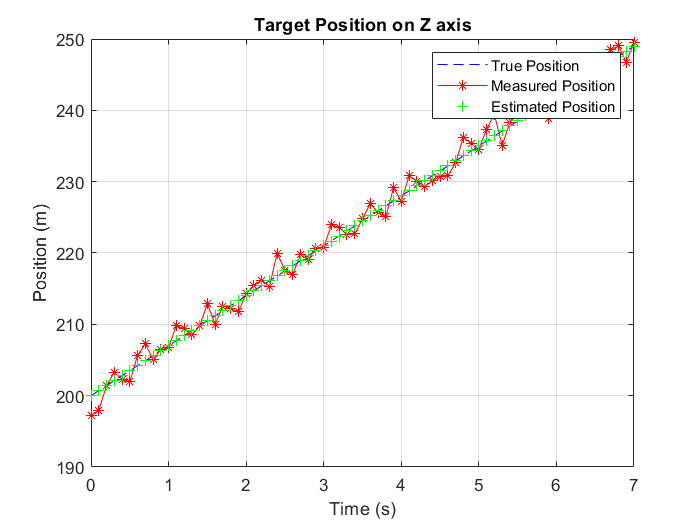

% subplot(313)
figure
% plot(t,Ztrue(3,:),'r','LineWidth',1.5)
% hold on
% plot(t,Znoisy(3,:),'g','LineWidth',1.5)
% hold on
% plot(t,Estimate(3,:),'b','LineWidth',1.5)
plot(t,Ztrue(3,:),'--b',t,Znoisy(3,:),'r-*',t,Estimate(3,:),'g+')
legend('True Position','Measured Position','Estimated Position')
xlabel('Time (s)')
ylabel('Position (m)')
title('Target Position on Z axis')
grid on
hold off

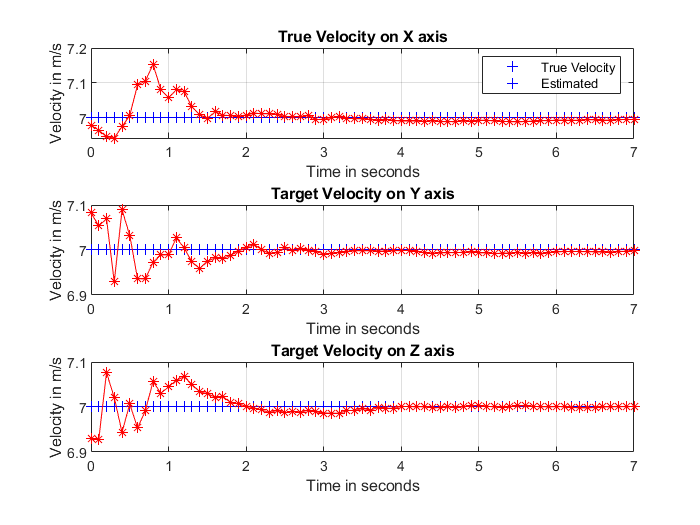

figure
plot(t,V(1,:),'r','LineWidth',1.5)
hold on
plot(t,Estimate(4,:),'b','LineWidth',1.5)
subplot(3,1,1)
plot(t,V(1,:),'+b',t,Estimate(4,:),'r-*')
legend('True Velocity','Estimated')
xlabel('Time in seconds')
ylabel('Velocity in m/s')
title('True Velocity on X axis')
grid on
hold off
% plot(t,V(2,:),'r')
% hold on
% plot(t,Estimate(5,:),'b','LineWidth',1.5)
subplot(3,1,2)
plot(t,V(2,:),'+b',t,Estimate(5,:),'r-*')
xlabel('Time in seconds')
ylabel('Velocity in m/s')
title('Target Velocity on Y axis')
grid on
hold off
% plot(t,V(3,:),'r')
% hold on
% plot(t,Estimate(6,:),'b','LineWidth',1.5)
subplot(3,1,3)
plot(t,V(3,:),'+b',t,Estimate(6,:),'r-*')
xlabel('Time in seconds')
ylabel('Velocity in m/s')
title('Target Velocity on Z axis')
grid on
hold off

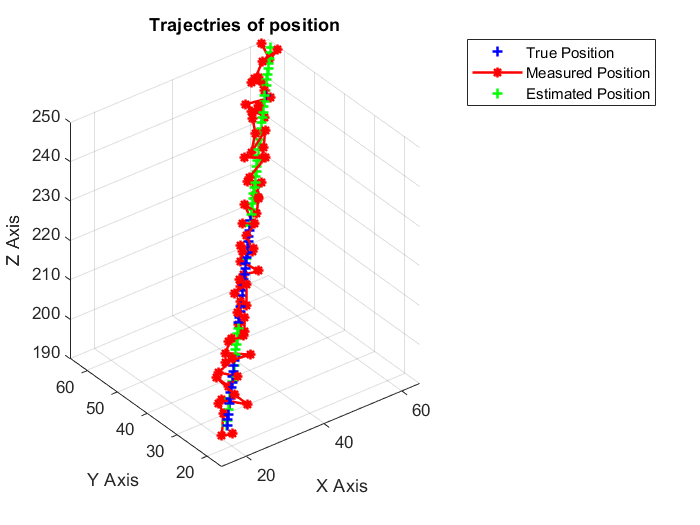

figure
plot3(Ztrue(1,:),Ztrue(2,:),Ztrue(3,:),'+b',Znoisy(1,:),Znoisy(2,:),Znoisy(3,:),'r-*',Estimate(1,:),Estimate(2,:),Estimate(3,:),'g+','LineWidth',1.5)
legend('True Position ','Measured Position ','Estimated Position ')
title('Trajectries of position')
xlabel('X Axis');
ylabel('Y Axis');
zlabel('Z Axis')
grid on
hold off

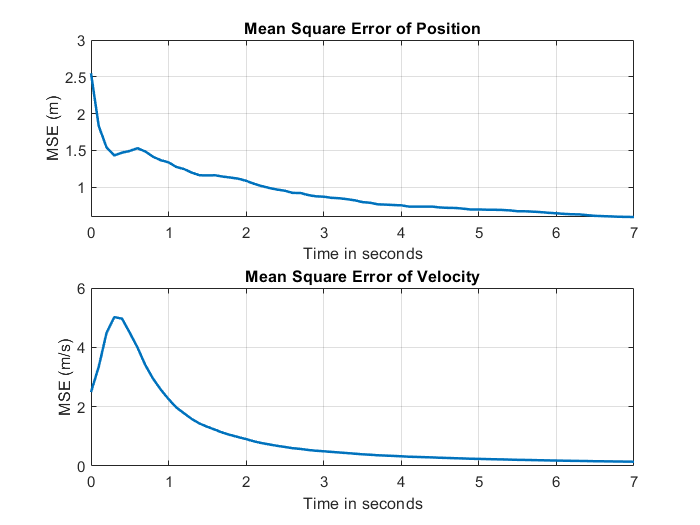

figure
subplot(211)
plot(t,PositionRMSE, 'LineWidth',1.5)
xlabel('Time in seconds')
ylabel('MSE (m)')
title('Mean Square Error of Position')
grid on
% figure
subplot(212);
plot(t,VelocityRMSE,'LineWidth',1.5);
xlabel('Time in seconds')
ylabel('MSE (m/s)')
title('Mean Square Error of Velocity')
grid on